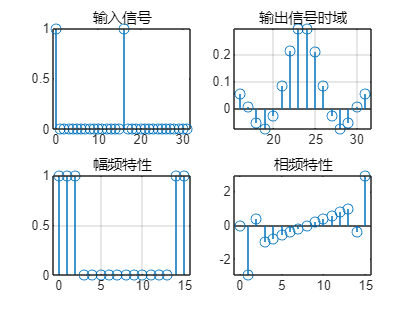

clc;clear;
f = 50;  % 基波频率
N = 16;  % 采样频率倍数
L = 2 * N;  % 采样点数
fs = N * f;  % 采样频率
T = 1 / fs;  % 采样间隔
t = (0:L-1) * T;  % 采样时间
%构造输入信号
x=zeros(1,2*N);
x(1)=1;
x(N+1)=1;
r=0.999;
y=CombFilter(x,N,r);
y1=zeros;
H = zeros(1, N); % 初始化频域响应
H(1) = 1; 
H(2) = exp(-1i*pi*(N-1)/N);
H(3) = exp(-1i*2*pi*(N-1)/N);
H(15) = -exp(-1i*14*pi*(N-1)/N); 
H(16) = -exp(-1i*15*pi*(N-1)/N); 
for i=0:1:(N/2)
    ord=i;
    y1=y1+Resonator2(y,N,r,ord,H(i+1));
end
y0=y1/N;
k=N:2*N-1;
hold on
figure(1);
subplot(2,2,1)
stem(0:2*N-1,x);
title('输入信号');
subplot(2,2,2);
stem(k,y0(k+1));
title('输出信号时域');
grid on;
Y=zeros(1,N);
for i=N:1:2*N-1
    Y(i-N+1)=y0(i+1);
end
YY=fft(Y);
k=0:1:N-1;
hold on;
subplot(2,2,3);
stem(k,abs(YY(k+1)));
title('幅频特性');
grid on;
subplot(2,2,4);
stem(k,angle(YY(k+1)));
title('相频特性')